# Impedance matching considering electrical power

## Derive analytical expression for voltageRatio

% page 89 notebook - 1/27/24
clear all
syms z1 z2 alpha real
z = z1 + 1i * z2;
complex_term = z * (1 - alpha * 1i) ./ (1 + z + (1 - z)*alpha*1i);
voltageRatio = 2/sqrt(1 + alpha^2) * abs(complex_term);
voltageRatio = simplify(voltageRatio)

$$voltageRatio = \frac{2\,\sqrt{{z_{1}}^{2}+{z_{2}}^{2}}}{\sqrt{{\left(z_{1}+\alpha \,z_{2}+1\right)}^{2}+{\left(z_{2}-\alpha \,\left(z_{1}-1\right)\right)}^{2}}}$$


syms g_mag g_ang real
gamma = g_mag * exp(1i*g_ang);
real_z_terms_of_gamma = real(-(gamma + 1) / (gamma - 1));
imag_z_terms_of_gamma = imag(-(gamma + 1) / (gamma - 1));

voltageRatio = subs(voltageRatio,{z1,z2},{real_z_terms_of_gamma,imag_z_terms_of_gamma});
voltageRatio = simplify(voltageRatio,100)

$$voltageRatio = \frac{\sqrt{{g_{\mathrm{mag}}}^{2}+2\,\cos\left(g_{\mathrm{ang}}\right)\,g_{\mathrm{mag}}+1}}{\sqrt{\alpha^{2}\,{g_{\mathrm{mag}}}^{2}+2\,\sin\left(g_{\mathrm{ang}}\right)\,\alpha \,g_{\mathrm{mag}}+1}}$$


assumeAlso(g_mag,'positive')
voltageDerivEqn = simplify(diff(voltageRatio,g_ang) == 0);
%secondDeriv = diff(voltageRatio,g_ang,2);

%assume(secondDeriv,'positive')
g_ang_opt = solve(voltageDerivEqn,g_ang,'Real',true)

$$g\_ang\_opt = \begin{array}{l} \left(\begin{array}{c} 2\,\mathrm{atan}\left(\frac{\alpha^{2}\,{g_{\mathrm{mag}}}^{2}-\sigma_{1}+1}{\alpha \,{g_{\mathrm{mag}}}^{2}-2\,\alpha \,g_{\mathrm{mag}}+\alpha }\right)\\ 2\,\mathrm{atan}\left(\frac{\sigma_{1}+\alpha^{2}\,{g_{\mathrm{mag}}}^{2}+1}{\alpha \,{g_{\mathrm{mag}}}^{2}-2\,\alpha \,g_{\mathrm{mag}}+\alpha }\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{\left(\alpha^{2}+1\right)\,\left(\alpha^{2}\,{g_{\mathrm{mag}}}^{4}+1\right)} \end{array}$$

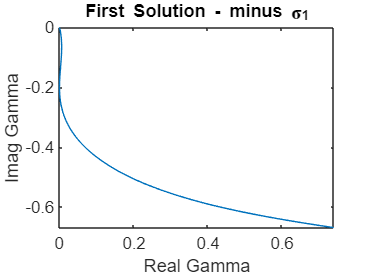

%secondDeriv = subs(secondDeriv,g_ang,g_ang_opt);
%simplify(secondDeriv > 0)

% plot to figure out if I should use first or second
% looks like second because it has negative real, positive imaginary, and
% the right shape when compared to my numerical smith charts
g_opt = g_mag * exp(1i*g_ang_opt);
gx = subs(real(g_opt),alpha,5);
gy = subs(imag(g_opt),alpha,5);
figure
fplot(gx(1),gy(1),[0 1])
title('First Solution - minus \sigma_1')
xlabel('Real Gamma')
ylabel('Imag Gamma')

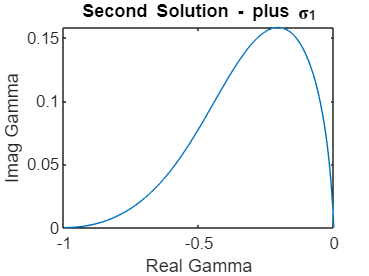

figure
fplot(gx(2),gy(2),[0 1])
title('Second Solution - plus \sigma_1')
xlabel('Real Gamma')
ylabel('Imag Gamma')


%voltage_ratio_opt = simplify(subs(voltageRatio,g_ang,g_ang_opt(2)),'Steps',100)

## Derive analytical expression for current ratio

absZ = sqrt(real_z_terms_of_gamma^2 + imag_z_terms_of_gamma^2);
currentRatio = simplify(voltageRatio / absZ)

$$currentRatio = \frac{\sqrt{{g_{\mathrm{mag}}}^{2}-2\,\cos\left(g_{\mathrm{ang}}\right)\,g_{\mathrm{mag}}+1}}{\sqrt{\alpha^{2}\,{g_{\mathrm{mag}}}^{2}+2\,\sin\left(g_{\mathrm{ang}}\right)\,\alpha \,g_{\mathrm{mag}}+1}}$$

currentDerivEqn = simplify(diff(currentRatio,g_ang) == 0,'Steps',100);
g_ang_opt_current = solve(currentDerivEqn,g_ang,'Real',true)

$$g\_ang\_opt\_current = \begin{array}{l} \left(\begin{array}{c} -2\,\mathrm{atan}\left(\frac{\alpha^{2}\,{g_{\mathrm{mag}}}^{2}-\sigma_{1}+1}{\alpha \,{g_{\mathrm{mag}}}^{2}+2\,\alpha \,g_{\mathrm{mag}}+\alpha }\right)\\ -2\,\mathrm{atan}\left(\frac{\sigma_{1}+\alpha^{2}\,{g_{\mathrm{mag}}}^{2}+1}{\alpha \,{g_{\mathrm{mag}}}^{2}+2\,\alpha \,g_{\mathrm{mag}}+\alpha }\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{\left(\alpha^{2}+1\right)\,\left(\alpha^{2}\,{g_{\mathrm{mag}}}^{4}+1\right)} \end{array}$$

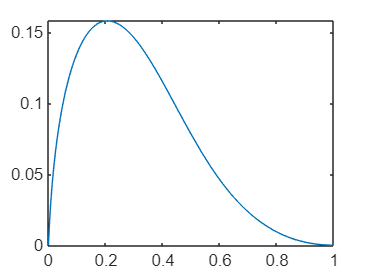


% plot to figure out if I should use first or second - looks like the first
g_opt = g_mag * exp(1i*g_ang_opt_current);
gx = subs(real(g_opt),alpha,5);
gy = subs(imag(g_opt),alpha,5);
figure
fplot(gx(1),gy(1),[0 1])

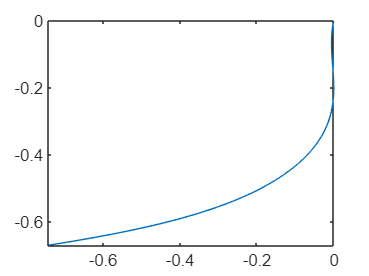

figure
fplot(gx(2),gy(2),[0 1])


%current_ratio_opt = simplify(subs(currentRatio,g_ang,g_ang_opt_current(1)),'Steps',100)

## combine current and voltage ratios into one eqn with epsilon

syms epsilon real % 1 -1 indicator for voltage vs current

num = g_mag^2 + epsilon*2*cos(g_ang)*g_mag + 1;
den = alpha^2*g_mag^2 + 2*alpha*sin(g_ang)*g_mag + 1;
ratios = sqrt(num) / sqrt(den)

$$ratios = \frac{\sqrt{{g_{\mathrm{mag}}}^{2}+2\,\epsilon \,\cos\left(g_{\mathrm{ang}}\right)\,g_{\mathrm{mag}}+1}}{\sqrt{\alpha^{2}\,{g_{\mathrm{mag}}}^{2}+2\,\sin\left(g_{\mathrm{ang}}\right)\,\alpha \,g_{\mathrm{mag}}+1}}$$


assert(subs(ratios,epsilon, 1)==voltageRatio)
assert(subs(ratios,epsilon,-1)==currentRatio)

## Rederive using the all-quadrant atan from Otoshi 1994 paper

% next notebook page 83 6/22/24
coeffsVoltage = fliplr(coeffs(lhs(voltageDerivEqn)-rhs(voltageDerivEqn),[cos(g_ang),sin(g_ang)]));
coeffsCurrent = fliplr(coeffs(lhs(currentDerivEqn)-rhs(currentDerivEqn),[cos(g_ang),sin(g_ang)]));

D = coeffsVoltage(1); assert(-D == coeffsCurrent(1)); % cos
E = coeffsVoltage(2); assert( E == coeffsCurrent(2)); % sin
C = coeffsVoltage(3); assert( C == coeffsCurrent(3)); % const

acos_term = acos(-C / sqrt(D^2+E^2));
atan_term = 2*atan(E / (sqrt(D^2+E^2) + epsilon*D));
g_ang_opt = atan_term + epsilon * acos_term

$$g\_ang\_opt = \begin{array}{l} 2\,\mathrm{atan}\left(\frac{\alpha^{2}\,{g_{\mathrm{mag}}}^{2}+1}{\sigma_{1}+\epsilon \,\left(\alpha \,{g_{\mathrm{mag}}}^{2}+\alpha \right)}\right)+\epsilon \,\left(\pi -\mathrm{acos}\left(\frac{2\,\alpha \,g_{\mathrm{mag}}}{\sigma_{1}}\right)\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{{\left(\alpha^{2}\,{g_{\mathrm{mag}}}^{2}+1\right)}^{2}+{\left(\alpha \,{g_{\mathrm{mag}}}^{2}+\alpha \right)}^{2}} \end{array}$$

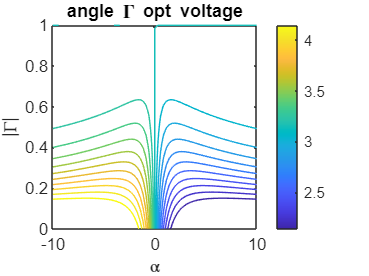


g_ang_opt_voltage = subs(g_ang_opt,epsilon,1);
g_ang_opt_current = subs(g_ang_opt,epsilon,-1);

fcontour(g_ang_opt_voltage,[-10 10 0 1],'LevelList',pi + (-1:.1:1))
xlabel('\alpha')
ylabel('|\Gamma|')
title('angle \Gamma opt voltage')
colorbar

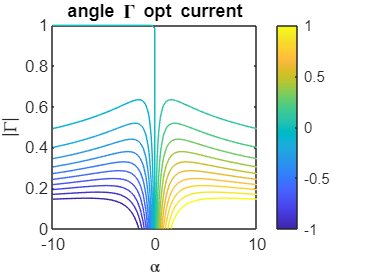


fcontour(g_ang_opt_current,[-10 10 0 1],'LevelList',-1:.1:1)
xlabel('\alpha')
ylabel('|\Gamma|')
title('angle \Gamma opt current')
colorbar

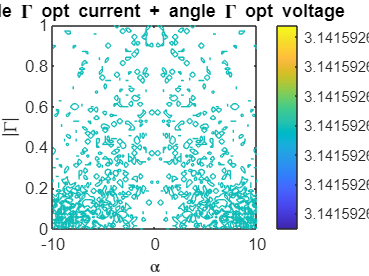


should_be_pi = g_ang_opt_voltage + g_ang_opt_current;
fcontour(should_be_pi,[-10 10 0 1])
xlabel('\alpha')
ylabel('|\Gamma|')
title('angle \Gamma opt current + angle \Gamma opt voltage')
colorbar


angles_supp = pi == should_be_pi;
isAlways(angles_supp)

ans = logical
   0


solve(angles_supp,'Real',true)

 
ans =
 
Empty sym: 0-by-1
 



% matlab can't figure out how to prove it but it's numerically clear that 
% the angles are supplementary, so use that fact to plug in to find ratios_opt.
% I proved geometrically that they are supplementray on p85-86 of notebook 6/22/24.

g_ang_opt_current = pi - g_ang_opt_voltage;

voltage_ratio_opt = subs(ratios,{g_ang,epsilon},{g_ang_opt_voltage,1})

$$voltage\_ratio\_opt = \begin{array}{l} \frac{\sqrt{{g_{\mathrm{mag}}}^{2}-2\,g_{\mathrm{mag}}\,\cos\left(\sigma_{1}\right)+1}}{\sqrt{\alpha^{2}\,{g_{\mathrm{mag}}}^{2}+2\,\alpha \,g_{\mathrm{mag}}\,\sin\left(\sigma_{1}\right)+1}}\\ \mathrm{where}\\ \sigma_{1}=\mathrm{acos}\left(\frac{2\,\alpha \,g_{\mathrm{mag}}}{\sqrt{{\left(\alpha^{2}\,{g_{\mathrm{mag}}}^{2}+1\right)}^{2}+{\left(\alpha \,{g_{\mathrm{mag}}}^{2}+\alpha \right)}^{2}}}\right)-2\,\mathrm{atan}\left(\frac{\alpha^{2}\,{g_{\mathrm{mag}}}^{2}+1}{\alpha +\sqrt{{\left(\alpha^{2}\,{g_{\mathrm{mag}}}^{2}+1\right)}^{2}+{\left(\alpha \,{g_{\mathrm{mag}}}^{2}+\alpha \right)}^{2}}+\alpha \,{g_{\mathrm{mag}}}^{2}}\right) \end{array}$$

current_ratio_opt = subs(ratios,{g_ang,epsilon},{g_ang_opt_current,-1})

$$current\_ratio\_opt = \begin{array}{l} \frac{\sqrt{{g_{\mathrm{mag}}}^{2}-2\,g_{\mathrm{mag}}\,\cos\left(\sigma_{1}\right)+1}}{\sqrt{\alpha^{2}\,{g_{\mathrm{mag}}}^{2}+2\,\alpha \,g_{\mathrm{mag}}\,\sin\left(\sigma_{1}\right)+1}}\\ \mathrm{where}\\ \sigma_{1}=\mathrm{acos}\left(\frac{2\,\alpha \,g_{\mathrm{mag}}}{\sqrt{{\left(\alpha^{2}\,{g_{\mathrm{mag}}}^{2}+1\right)}^{2}+{\left(\alpha \,{g_{\mathrm{mag}}}^{2}+\alpha \right)}^{2}}}\right)-2\,\mathrm{atan}\left(\frac{\alpha^{2}\,{g_{\mathrm{mag}}}^{2}+1}{\alpha +\sqrt{{\left(\alpha^{2}\,{g_{\mathrm{mag}}}^{2}+1\right)}^{2}+{\left(\alpha \,{g_{\mathrm{mag}}}^{2}+\alpha \right)}^{2}}+\alpha \,{g_{\mathrm{mag}}}^{2}}\right) \end{array}$$


ratios_equal = voltage_ratio_opt == current_ratio_opt;
simplify(ratios_equal,'Steps',100)

$$ans = \mathrm{symtrue}$$

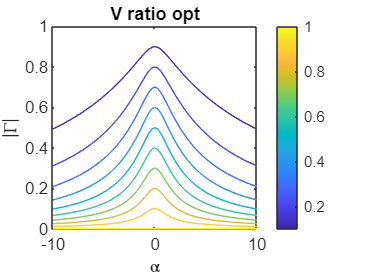


fcontour(voltage_ratio_opt,[-10 10 0 1],'LevelList',0:.1:10)
colorbar
xlabel('\alpha')
ylabel('|\Gamma|')
title('V ratio opt')

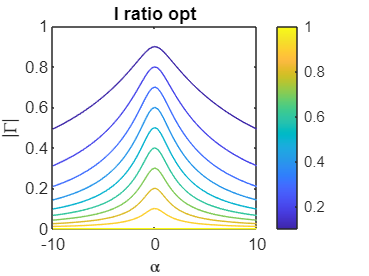


fcontour(current_ratio_opt,[-10 10 0 1],'LevelList',0:.1:10)
colorbar
xlabel('\alpha')
ylabel('|\Gamma|')
title('I ratio opt')

## deriving power vs optimal voltage/current ratio

% see notebook p99 6/24/24
% should be a quadratic for Gamma_mag

syms R real positive % ratio (current or voltage)
assumeAlso(abs(epsilon)==1)
g_mag_sol = solve(ratios^2-R^2,g_mag)

$$g\_mag\_sol = \begin{array}{l} \left(\begin{array}{c} \frac{\epsilon \,\cos\left(g_{\mathrm{ang}}\right)+\sigma_{1}-R^{2}\,\alpha \,\sin\left(g_{\mathrm{ang}}\right)}{R^{2}\,\alpha^{2}-1}\\ -\frac{\sigma_{1}-\epsilon \,\cos\left(g_{\mathrm{ang}}\right)+R^{2}\,\alpha \,\sin\left(g_{\mathrm{ang}}\right)}{R^{2}\,\alpha^{2}-1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{R^{4}\,\alpha^{2}\,{\sin\left(g_{\mathrm{ang}}\right)}^{2}-R^{4}\,\alpha^{2}+R^{2}\,\alpha^{2}-2\,R^{2}\,\alpha \,\epsilon \,\cos\left(g_{\mathrm{ang}}\right)\,\sin\left(g_{\mathrm{ang}}\right)+R^{2}+\epsilon^{2}\,{\cos\left(g_{\mathrm{ang}}\right)}^{2}-1} \end{array}$$

simplify(g_mag_sol > 0)

$$ans = \begin{array}{l} \left(\begin{array}{c} 0<\frac{\epsilon \,\cos\left(g_{\mathrm{ang}}\right)+\sigma_{1}-R^{2}\,\alpha \,\sin\left(g_{\mathrm{ang}}\right)}{R^{2}\,\alpha^{2}-1}\\ \frac{\sigma_{1}-\epsilon \,\cos\left(g_{\mathrm{ang}}\right)+R^{2}\,\alpha \,\sin\left(g_{\mathrm{ang}}\right)}{R^{2}\,\alpha^{2}-1}<0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{-R^{4}\,\alpha^{2}\,{\cos\left(g_{\mathrm{ang}}\right)}^{2}+R^{2}\,\alpha^{2}-\sin\left(2\,g_{\mathrm{ang}}\right)\,R^{2}\,\alpha \,\epsilon +R^{2}+\epsilon^{2}\,{\cos\left(g_{\mathrm{ang}}\right)}^{2}-1} \end{array}$$

Gamma_mag_opt_V = subs(g_mag_sol,{g_ang,epsilon},{g_ang_opt_voltage,1})

$$Gamma\_mag\_opt\_V = \begin{array}{l} \left(\begin{array}{c} -\frac{\sigma_{2}-\sigma_{1}+R^{2}\,\alpha \,\sigma_{3}}{R^{2}\,\alpha^{2}-1}\\ -\frac{\sigma_{2}+\sigma_{1}+R^{2}\,\alpha \,\sigma_{3}}{R^{2}\,\alpha^{2}-1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{R^{4}\,\alpha^{2}\,{\sigma_{3}}^{2}-R^{4}\,\alpha^{2}+R^{2}\,\alpha^{2}+2\,R^{2}\,\alpha \,\sigma_{2}\,\sigma_{3}+R^{2}+{\sigma_{2}}^{2}-1}\\ \sigma_{2}=\cos\left(\mathrm{acos}\left(\frac{2\,\alpha \,g_{\mathrm{mag}}}{\sigma_{4}}\right)-2\,\mathrm{atan}\left(\frac{\alpha^{2}\,{g_{\mathrm{mag}}}^{2}+1}{\alpha +\sigma_{4}+\alpha \,{g_{\mathrm{mag}}}^{2}}\right)\right)\\ \sigma_{3}=\sin\left(\mathrm{acos}\left(\frac{2\,\alpha \,g_{\mathrm{mag}}}{\sigma_{4}}\right)-2\,\mathrm{atan}\left(\frac{\alpha^{2}\,{g_{\mathrm{mag}}}^{2}+1}{\alpha +\sigma_{4}+\alpha \,{g_{\mathrm{mag}}}^{2}}\right)\right)\\ \sigma_{4}=\sqrt{{\left(\alpha^{2}\,{g_{\mathrm{mag}}}^{2}+1\right)}^{2}+{\left(\alpha \,{g_{\mathrm{mag}}}^{2}+\alpha \right)}^{2}} \end{array}$$

Gamma_mag_opt_I = subs(g_mag_sol,{g_ang,epsilon},{g_ang_opt_current,-1})

$$Gamma\_mag\_opt\_I = \begin{array}{l} \left(\begin{array}{c} -\frac{\sigma_{2}-\sigma_{1}+R^{2}\,\alpha \,\sigma_{3}}{R^{2}\,\alpha^{2}-1}\\ -\frac{\sigma_{2}+\sigma_{1}+R^{2}\,\alpha \,\sigma_{3}}{R^{2}\,\alpha^{2}-1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{R^{4}\,\alpha^{2}\,{\sigma_{3}}^{2}-R^{4}\,\alpha^{2}+R^{2}\,\alpha^{2}+2\,R^{2}\,\alpha \,\sigma_{2}\,\sigma_{3}+R^{2}+{\sigma_{2}}^{2}-1}\\ \sigma_{2}=\cos\left(\mathrm{acos}\left(\frac{2\,\alpha \,g_{\mathrm{mag}}}{\sigma_{4}}\right)-2\,\mathrm{atan}\left(\frac{\alpha^{2}\,{g_{\mathrm{mag}}}^{2}+1}{\alpha +\sigma_{4}+\alpha \,{g_{\mathrm{mag}}}^{2}}\right)\right)\\ \sigma_{3}=\sin\left(\mathrm{acos}\left(\frac{2\,\alpha \,g_{\mathrm{mag}}}{\sigma_{4}}\right)-2\,\mathrm{atan}\left(\frac{\alpha^{2}\,{g_{\mathrm{mag}}}^{2}+1}{\alpha +\sigma_{4}+\alpha \,{g_{\mathrm{mag}}}^{2}}\right)\right)\\ \sigma_{4}=\sqrt{{\left(\alpha^{2}\,{g_{\mathrm{mag}}}^{2}+1\right)}^{2}+{\left(\alpha \,{g_{\mathrm{mag}}}^{2}+\alpha \right)}^{2}} \end{array}$$


difference = simplify(Gamma_mag_opt_V - Gamma_mag_opt_I,'Steps',100)

$$difference = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

% this doesn't work because Gamma_mag is on both sides of the equation
% try again, this time solving based on the optimal ratio directly
g_mag_opt = solve(voltage_ratio_opt^2 - R^2, g_mag)

 
g_mag_opt =
 
Empty sym: 0-by-1
 


% stop this path and go to section below where I do the trig myself to
% simplify sin(g_ang) and cos(g_ang), since matlab won't do it.

## trying to derive expression for pareto front

% page 87-89 notebook 6/22/24
clear C D E
syms v real positive
D = 2*g_mag;
E = -v^2 * 2 * alpha * g_mag;
C = 1 + g_mag^2 - v^2 * (1 + alpha^2 * g_mag^2);

Delta = D^2 + E^2;

term = (D+sqrt(Delta))*sqrt(Delta^2 - C^2) - E*C;
sinGamma = (2*D^2 + E^2 * 2*D*sqrt(Delta)) * term / (Delta * (D + sqrt(Delta))^2);
sinGamma = simplify(sinGamma,'Steps',100)

$$sinGamma = \begin{array}{l} \frac{\left(2\,g_{\mathrm{mag}}\,\left(\sqrt{\sigma_{1}}+1\right)\,\sqrt{16\,{g_{\mathrm{mag}}}^{4}\,{\sigma_{1}}^{2}-{\sigma_{2}}^{2}}+2\,\alpha \,g_{\mathrm{mag}}\,v^{2}\,\sigma_{2}\right)\,\left(4\,\alpha^{2}\,{g_{\mathrm{mag}}}^{2}\,v^{4}\,\sqrt{\sigma_{1}}+1\right)}{2\,{g_{\mathrm{mag}}}^{2}\,{\left(\sqrt{\sigma_{1}}+1\right)}^{2}\,\sigma_{1}}\\ \mathrm{where}\\ \sigma_{1}=\alpha^{2}\,v^{4}+1\\ \sigma_{2}=-\alpha^{2}\,{g_{\mathrm{mag}}}^{2}\,v^{2}+{g_{\mathrm{mag}}}^{2}-v^{2}+1 \end{array}$$


num = 2*(1+g_mag^2);
den = 1 + alpha^2*g_mag^2 + 2*alpha*g_mag * sinGamma;
i_in_terms_of_v = sqrt(num / den - v^2);

assumeAlso(g_mag <= 1)
i_in_terms_of_v = simplify(i_in_terms_of_v,'Steps',100)

$$i\_in\_terms\_of\_v = \begin{array}{l} \sqrt{\frac{2\,{g_{\mathrm{mag}}}^{2}+2}{\alpha^{2}\,{g_{\mathrm{mag}}}^{2}+\frac{\alpha \,\left(2\,g_{\mathrm{mag}}\,\left(\sqrt{\sigma_{1}}+1\right)\,\sqrt{16\,{g_{\mathrm{mag}}}^{4}\,{\sigma_{1}}^{2}-{\sigma_{2}}^{2}}+2\,\alpha \,g_{\mathrm{mag}}\,v^{2}\,\sigma_{2}\right)\,\left(4\,\alpha^{2}\,{g_{\mathrm{mag}}}^{2}\,v^{4}\,\sqrt{\sigma_{1}}+1\right)}{g_{\mathrm{mag}}\,{\left(\sqrt{\sigma_{1}}+1\right)}^{2}\,\sigma_{1}}+1}-v^{2}}\\ \mathrm{where}\\ \sigma_{1}=\alpha^{2}\,v^{4}+1\\ \sigma_{2}=-\alpha^{2}\,{g_{\mathrm{mag}}}^{2}\,v^{2}+{g_{\mathrm{mag}}}^{2}-v^{2}+1 \end{array}$$

## check answer to make sure I did it right


i_in_terms_of_v_test = subs(i_in_terms_of_v,alpha,2);
% this plot takes forever to run and gets stuck
% figure
% for gamma_test = [0.1 0.2]%0.1 : 0.1 : .9
%     expr = subs(i_in_terms_of_v_test,g_mag,gamma_test);
%     fplot(expr,[0 1],'MeshDensity',4)
%     hold on
%     disp(['finished ' num2str(gamma_test)])
% end

## use sinGamma to get pareto front just for optimal case

% notebook p100-101, 6/25/24
termSum = D^2 + 1/2*E^2 + D*sqrt(Delta);
term1 = 2*C/sqrt(Delta)*termSum;
term2 = 2*E* sqrt( termSum * (Delta^2 - C^2) / (Delta+D*Delta)) ;
cosGamma = 1/(D*sqrt(Delta)+Delta) * (term1 + term2);
cosGamma = simplify(cosGamma,'Steps',100)

$$cosGamma = \begin{array}{l} \frac{\frac{g_{\mathrm{mag}}\,\sigma_{1}\,\left(-2\,\alpha^{2}\,{g_{\mathrm{mag}}}^{2}\,v^{2}+2\,{g_{\mathrm{mag}}}^{2}-2\,v^{2}+2\right)}{\sqrt{\sigma_{2}+1}}-\frac{2\,\sqrt{2}\,\alpha \,g_{\mathrm{mag}}\,v^{2}\,\sqrt{16\,{g_{\mathrm{mag}}}^{4}\,{\left(\sigma_{2}+1\right)}^{2}-{\left(-\alpha^{2}\,{g_{\mathrm{mag}}}^{2}\,v^{2}+{g_{\mathrm{mag}}}^{2}-v^{2}+1\right)}^{2}}\,\sqrt{\sigma_{1}}}{\sqrt{2\,g_{\mathrm{mag}}+1}\,\sqrt{\sigma_{2}+1}}}{4\,{g_{\mathrm{mag}}}^{2}\,\left(\sqrt{\sigma_{2}+1}+\sigma_{2}+1\right)}\\ \mathrm{where}\\ \sigma_{1}=2\,\sqrt{\sigma_{2}+1}+\sigma_{2}+2\\ \sigma_{2}=\alpha^{2}\,v^{4} \end{array}$$


g_mag_general = subs(g_mag_sol,{cos(g_ang),sin(g_ang),R},{cosGamma,sinGamma,v});
power_general = simplify(1-g_mag_general.^2,'Steps',100)

$$power\_general = \begin{array}{l} \left(\begin{array}{c} 1-\frac{{\left(\sigma_{1}+\sigma_{3}-\sigma_{2}\right)}^{2}}{{\left(\sigma_{4}-1\right)}^{2}}\\ 1-\frac{{\left(\sigma_{1}-\sigma_{3}+\sigma_{2}\right)}^{2}}{{\left(\sigma_{4}-1\right)}^{2}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{v^{2}+\sigma_{4}-\sigma_{13}+\frac{\epsilon^{2}\,{\sigma_{7}}^{2}}{16\,{g_{\mathrm{mag}}}^{4}\,{\sigma_{8}}^{2}}+\frac{\alpha^{2}\,v^{4}\,{\left(g_{\mathrm{mag}}\,\sigma_{9}\,\sigma_{10}+\alpha \,g_{\mathrm{mag}}\,v^{2}\,\sigma_{12}\right)}^{2}\,{\sigma_{6}}^{2}}{{g_{\mathrm{mag}}}^{4}\,{\sigma_{9}}^{4}\,{\left(\sigma_{13}+1\right)}^{2}}-\frac{\alpha \,\epsilon \,v^{2}\,\sigma_{7}\,\sigma_{5}\,\sigma_{6}}{4\,{g_{\mathrm{mag}}}^{4}\,{\sigma_{9}}^{2}\,\left(\sigma_{13}+1\right)\,\sigma_{8}}-1}\\ \sigma_{2}=\frac{\alpha \,v^{2}\,\sigma_{5}\,\sigma_{6}}{2\,{g_{\mathrm{mag}}}^{2}\,{\sigma_{9}}^{2}\,\left(\sigma_{13}+1\right)}\\ \sigma_{3}=\frac{\epsilon \,\sigma_{7}}{4\,{g_{\mathrm{mag}}}^{2}\,\sigma_{8}}\\ \sigma_{4}=\alpha^{2}\,v^{2}\\ \sigma_{5}=2\,g_{\mathrm{mag}}\,\sigma_{9}\,\sigma_{10}+2\,\alpha \,g_{\mathrm{mag}}\,v^{2}\,\sigma_{12}\\ \sigma_{6}=4\,\alpha^{2}\,{g_{\mathrm{mag}}}^{2}\,v^{4}\,\sqrt{\sigma_{13}+1}+1\\ \sigma_{7}=\frac{g_{\mathrm{mag}}\,\sigma_{11}\,\left(-2\,\alpha^{2}\,{g_{\mathrm{mag}}}^{2}\,v^{2}+2\,{g_{\mathrm{mag}}}^{2}-2\,v^{2}+2\right)}{\sqrt{\sigma_{13}+1}}-\frac{2\,\sqrt{2}\,\alpha \,g_{\mathrm{mag}}\,v^{2}\,\sigma_{10}\,\sqrt{\sigma_{11}}}{\sqrt{2\,g_{\mathrm{mag}}+1}\,\sqrt{\sigma_{13}+1}}\\ \sigma_{8}=\sqrt{\sigma_{13}+1}+\sigma_{13}+1\\ \sigma_{9}=\sqrt{\sigma_{13}+1}+1\\ \sigma_{10}=\sqrt{16\,{g_{\mathrm{mag}}}^{4}\,{\left(\sigma_{13}+1\right)}^{2}-{\sigma_{12}}^{2}}\\ \sigma_{11}=2\,\sqrt{\sigma_{13}+1}+\sigma_{13}+2\\ \sigma_{12}=-\alpha^{2}\,{g_{\mathrm{mag}}}^{2}\,v^{2}+{g_{\mathrm{mag}}}^{2}-v^{2}+1\\ \sigma_{13}=\alpha^{2}\,v^{4} \end{array}$$

symvar(power_general)

$$ans = \left(\begin{array}{cccc} \alpha & \epsilon & g_{\mathrm{mag}} & v \end{array}\right)$$


power_optimum_V = subs(power_general,{v,epsilon},{voltage_ratio_opt,1})

%power_optimum_V = simplify(power_optimum_V,'Steps',100)

## Derive analytical expression for Gamma optimum for weighted objective

syms a b real positive
c = 1 - a - b;
assume(c,'positive')
powerRatio = 1 - g_mag^2;
J = simplify(a * powerRatio - b * voltageRatio - c * currentRatio)
dJdG = simplify(jacobian(J,[g_mag;g_ang]))
sol = solve(dJdG == 0,[g_mag,g_ang],'Real',true,'ReturnConditions',true,'IgnoreAnalyticConstraints', true);
simplify(sol.conditions)
% doesn't give a useful answer

## optimal $\alpha_m$ to maximize $\alpha$ - page 138 notebook

clear all
syms R_over_D L real positive
syms alpha_m real
U = R_over_D * (1+alpha_m^2);
alpha_m_eqn = 0 == alpha_m^2 * (U - 1) - (U + 1) + 2*L*alpha_m*U;
solve(alpha_m_eqn,alpha_m)

$$ans = \left(\begin{array}{c} -\frac{L\,\sqrt{R_{\mathrm{over},D}}+\sqrt{R_{\mathrm{over},D}\,L^{2}+R_{\mathrm{over},D}+1}}{\sqrt{R_{\mathrm{over},D}}}\\ -\frac{L\,\sqrt{R_{\mathrm{over},D}}-\sqrt{R_{\mathrm{over},D}\,L^{2}+R_{\mathrm{over},D}+1}}{\sqrt{R_{\mathrm{over},D}}} \end{array}\right)$$


% do derivative automatically and check I get same answer as eqn above 
alpha = (L - alpha_m/U) / (1+1/U);
alpha_m_opt = solve(diff(alpha,alpha_m),alpha_m)

$$alpha\_m\_opt = \left(\begin{array}{c} -\frac{L\,\sqrt{R_{\mathrm{over},D}}+\sqrt{R_{\mathrm{over},D}\,L^{2}+R_{\mathrm{over},D}+1}}{\sqrt{R_{\mathrm{over},D}}}\\ -\frac{L\,\sqrt{R_{\mathrm{over},D}}-\sqrt{R_{\mathrm{over},D}\,L^{2}+R_{\mathrm{over},D}+1}}{\sqrt{R_{\mathrm{over},D}}} \end{array}\right)$$


% they match great. now do sub back in to decide if I use + or -.
alpha_opt = subs(alpha,alpha_m,alpha_m_opt)

$$alpha\_opt = \begin{array}{l} \left(\begin{array}{c} \frac{L+\frac{L\,\sqrt{R_{\mathrm{over},D}}+\sqrt{R_{\mathrm{over},D}\,L^{2}+R_{\mathrm{over},D}+1}}{{R_{\mathrm{over},D}}^{3/2}\,\sigma_{2}}}{\frac{1}{R_{\mathrm{over},D}\,\sigma_{2}}+1}\\ \frac{L+\frac{L\,\sqrt{R_{\mathrm{over},D}}-\sqrt{R_{\mathrm{over},D}\,L^{2}+R_{\mathrm{over},D}+1}}{{R_{\mathrm{over},D}}^{3/2}\,\sigma_{1}}}{\frac{1}{R_{\mathrm{over},D}\,\sigma_{1}}+1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{{\left(L\,\sqrt{R_{\mathrm{over},D}}-\sqrt{R_{\mathrm{over},D}\,L^{2}+R_{\mathrm{over},D}+1}\right)}^{2}}{R_{\mathrm{over},D}}+1\\ \sigma_{2}=\frac{{\left(L\,\sqrt{R_{\mathrm{over},D}}+\sqrt{R_{\mathrm{over},D}\,L^{2}+R_{\mathrm{over},D}+1}\right)}^{2}}{R_{\mathrm{over},D}}+1 \end{array}$$

difference = abs(alpha_opt(1)) - abs(alpha_opt(2));
simplify(difference)

$$ans = \begin{array}{l} \frac{L\,\sqrt{R_{\mathrm{over},D}}+2\,L\,{R_{\mathrm{over},D}}^{3/2}+\sigma_{2}}{2\,\sqrt{R_{\mathrm{over},D}}\,\left(R_{\mathrm{over},D}+1\right)}-\frac{\left|L+\frac{L\,\sqrt{R_{\mathrm{over},D}}-\sigma_{2}}{\sqrt{R_{\mathrm{over},D}}\,\sigma_{1}}\right|}{\frac{1}{\sigma_{1}}+1}\\ \mathrm{where}\\ \sigma_{1}=2\,R_{\mathrm{over},D}+2\,L^{2}\,R_{\mathrm{over},D}-2\,L\,\sqrt{R_{\mathrm{over},D}}\,\sigma_{2}+1\\ \sigma_{2}=\sqrt{R_{\mathrm{over},D}\,L^{2}+R_{\mathrm{over},D}+1} \end{array}$$


% if difference is positive I should use +, if negative I should use -.
sol = solve(difference > 0,L,'ReturnConditions',true); sol.conditions

$$ans = \begin{array}{l} 2\,\sqrt{-R_{\mathrm{over},D}}+\frac{2\,R_{\mathrm{over},D}+1}{\sqrt{-R_{\mathrm{over},D}}}\neq 0\wedge 0<x\wedge \left(\left(0<\sigma_{3}\wedge \sigma_{2}<\sigma_{1}\right)\vee \left(0<\sigma_{1}+\sigma_{2}\wedge \sigma_{3}\leq 0\right)\right)\\ \mathrm{where}\\ \sigma_{1}=\left(\frac{1}{R_{\mathrm{over},D}\,\left(\frac{{\left(\sqrt{2\,R_{\mathrm{over},D}+1}-\sqrt{R_{\mathrm{over},D}}\right)}^{2}}{R_{\mathrm{over},D}}+1\right)}+1\right)\,\left(\frac{\sqrt{2\,R_{\mathrm{over},D}+1}+\sqrt{R_{\mathrm{over},D}}}{{R_{\mathrm{over},D}}^{3/2}\,\left(\frac{{\left(\sqrt{2\,R_{\mathrm{over},D}+1}+\sqrt{R_{\mathrm{over},D}}\right)}^{2}}{R_{\mathrm{over},D}}+1\right)}+1\right)\\ \sigma_{2}=\left(\frac{1}{R_{\mathrm{over},D}\,\left(\frac{{\left(\sqrt{2\,R_{\mathrm{over},D}+1}+\sqrt{R_{\mathrm{over},D}}\right)}^{2}}{R_{\mathrm{over},D}}+1\right)}+1\right)\,\left(\frac{\sqrt{2\,R_{\mathrm{over},D}+1}-\sqrt{R_{\mathrm{over},D}}}{{R_{\mathrm{over},D}}^{3/2}\,\left(\frac{{\left(\sqrt{2\,R_{\mathrm{over},D}+1}-\sqrt{R_{\mathrm{over},D}}\right)}^{2}}{R_{\mathrm{over},D}}+1\right)}-1\right)\\ \sigma_{3}={R_{\mathrm{over},D}}^{2}\,{\left(\frac{2}{\sqrt{R_{\mathrm{over},D}}}+\frac{1}{{R_{\mathrm{over},D}}^{3/2}}\right)}^{2}-4\,{\left(\sqrt{2\,R_{\mathrm{over},D}+1}-R_{\mathrm{over},D}\,\left(\frac{1}{\sqrt{R_{\mathrm{over},D}}}+\frac{1}{2\,{R_{\mathrm{over},D}}^{3/2}}\right)\right)}^{2}-8\,R_{\mathrm{over},D}-4 \end{array}$$

isAlways(sol.conditions)

ans = logical
   0



sol = solve(difference < 0,L,'ReturnConditions',true); sol.conditions

$$ans = \begin{array}{l} 2\,\sqrt{-R_{\mathrm{over},D}}+\frac{2\,R_{\mathrm{over},D}+1}{\sqrt{-R_{\mathrm{over},D}}}\neq 0\wedge 0<x\wedge \left(\left(0<\sigma_{3}\wedge \sigma_{1}<\sigma_{2}\right)\vee \left(\sigma_{1}+\sigma_{2}<0\wedge \sigma_{3}\leq 0\right)\right)\\ \mathrm{where}\\ \sigma_{1}=\left(\frac{1}{R_{\mathrm{over},D}\,\left(\frac{{\left(\sqrt{2\,R_{\mathrm{over},D}+1}-\sqrt{R_{\mathrm{over},D}}\right)}^{2}}{R_{\mathrm{over},D}}+1\right)}+1\right)\,\left(\frac{\sqrt{2\,R_{\mathrm{over},D}+1}+\sqrt{R_{\mathrm{over},D}}}{{R_{\mathrm{over},D}}^{3/2}\,\left(\frac{{\left(\sqrt{2\,R_{\mathrm{over},D}+1}+\sqrt{R_{\mathrm{over},D}}\right)}^{2}}{R_{\mathrm{over},D}}+1\right)}+1\right)\\ \sigma_{2}=\left(\frac{1}{R_{\mathrm{over},D}\,\left(\frac{{\left(\sqrt{2\,R_{\mathrm{over},D}+1}+\sqrt{R_{\mathrm{over},D}}\right)}^{2}}{R_{\mathrm{over},D}}+1\right)}+1\right)\,\left(\frac{\sqrt{2\,R_{\mathrm{over},D}+1}-\sqrt{R_{\mathrm{over},D}}}{{R_{\mathrm{over},D}}^{3/2}\,\left(\frac{{\left(\sqrt{2\,R_{\mathrm{over},D}+1}-\sqrt{R_{\mathrm{over},D}}\right)}^{2}}{R_{\mathrm{over},D}}+1\right)}-1\right)\\ \sigma_{3}={R_{\mathrm{over},D}}^{2}\,{\left(\frac{2}{\sqrt{R_{\mathrm{over},D}}}+\frac{1}{{R_{\mathrm{over},D}}^{3/2}}\right)}^{2}-4\,{\left(\sqrt{2\,R_{\mathrm{over},D}+1}-R_{\mathrm{over},D}\,\left(\frac{1}{\sqrt{R_{\mathrm{over},D}}}+\frac{1}{2\,{R_{\mathrm{over},D}}^{3/2}}\right)\right)}^{2}-8\,R_{\mathrm{over},D}-4 \end{array}$$

isAlways(sol.conditions)

ans = logical
   0


## same thing but for L=0 case

clear all
syms alpha_m R_over_D real
% eqn 8 of ifac paper with L=0
alpha = - alpha_m / (1 + R_over_D*(1+alpha_m^2));

alpha_m_opt = solve(diff(alpha,alpha_m),alpha_m)

$$alpha\_m\_opt = \left(\begin{array}{c} \sqrt{\frac{R_{\mathrm{over},D}+1}{R_{\mathrm{over},D}}}\\ -\sqrt{\frac{R_{\mathrm{over},D}+1}{R_{\mathrm{over},D}}} \end{array}\right)$$